# 1. Model Training: 

    Output of Section 1: 

        Feature .mat file containing variables:

                    **dat**

                            type: Cell array

                            dims: 1 by k, where k is number of classes annotated

                            contents: Each cell contains a matrix

                                    dims: ev by F, where ev is count of events of type k, and F is the total number of features extracted per epoch

                   ** sesID**

                            type: cell array

                            dims: 1 by k, where k is number of classes annotated

                            contents: Each cell contains a matrix

                                    dims: ev by 2, where ev is count of events of type k

                                        sesID{k}(ev, 1) = sesID for event ev of class k

                                        sesID{k}(ev, 2) = time in seconds marking beginning of event epoch

                    **sessions**

                            type: cell array

                            dims: nSessions by 5, where nSessions is number of recordings feature extraction was performed on

                            contents: 

                                sessions(nSession,1) = path to .evt.szr file containing manually-labled event timestamps from amplifier.lfp for recording session.     

                                        type: char

                                sessions(nSession,2) = path to amplifier.lfp file.     

                                        type: char

                                sessions(nSession,3) = path to sessiondata.mat file containing metadata about recording session.     

                                        type: char

                                sessions(nSession,4) = channels used for feature extraction from this session.  

                                        type: matrix 

                                sessions(nSession,5) = percent of each class used for feature extraction from this session. see ops.CohortSampling and ops.pct below 

                                        type: matrix 

                   ** ops**

                            type: struct

                            fields:

                               ** RawDataPath: **parent folders of data used for this feature extraction run

                                **CohortChannels: **like sessions(nSession,4), channels used for feature extraction for each folder in RawDataPath

                               ** CohortSampling: **like sessions(nSession,5), channels used for feature extraction for each folder in RawDataPath

                        **        FeaturePath, FeatureFileName, FeatureFileOutput: **paths which are used for saving the output file being described by this comment

                           **     bin_label, nBins:** names and count of classes for feature extraction and classification

                                **Fs **=  sampling frequency of .lfp files

                                **freqs **= frequency range and intervals used to feature extraction

                                **durFeat **= time series length, in seconds, of epochs/windows used for feature extraction 

                               ** art_thres** = artifact threshold for signal rejection (unused)

                              **  nCh_featureFile **= ? currently unused, vestigial

                             **   nCh_raw **= number of channels used to feature extraction

                               ** features **= @func alias for feature extraction function used for this run

                             **   ch_subj **= last channel indices used for feature extraction

                               ** pct **= last percent of each class used for feature extraction

# 1.a. Feature Generation

## 1.a.i. Dependencies

%DEPENDENCIES
% getAllExtFiles, sm_PredictIHKA_calcFeatures,sm_getPowerPerChannel,sm_MakeAll_getPowerPerChannel,
% getXPctTim, circ_corrcl

Must be added to MATLAB paths:  

R:\Analysis\buzcode-master

    circ_corrcl

R:\Analysis\McKenzieLab\Dat_helpers

R:\Analysis\McKenzieLab\helpers

    getAllExtFiles.m

    getXPctTim.m

    getlatestfile.m

R:\Analysis\McKenzieLab\SeizureForecasting\IHKA\

    sm_PredictIHKA_calcFeatures.m

    sm_GetDataFeature_rat.m

    sm_getPowerPerChannel.m

    sm_MakeAllgetPowerPerChannel.m

## 1.a.ii. Initialize Options

clear
clc





%% Create ops Struct for this feature extraction run

%% Parent folders of recordings
ops.RawDataPath = {'R:\DGregg\NeuralData\PTP\Recordings','R:\DGregg\NeuralData\PCP\Recordings',...
    'R:\ASommer\PilocarpineRecordings\PTP_5.1','R:\ASommer\PilocarpineRecordings\Tests\UnpluggedTest\2-17-2026(14.45)\RHS_260217_145001'};

%% Channel numbers for each parent folder
ops.CohortChannels = {[5,6],[5,6],[1,5],[1,5]};

%% Sampling per class for each parent folder
%% Used later to take X percent of total timepoints per class 
        %%  Based on index, i.e. [.1 .5 .5] takes 10% of class 1,
        %%  and 50% of classes 2 and 3 

ops.CohortSampling = {[.01 1 .2], [.01 1 .2], [.5 1 .2], [.5 1 .2]};

%% Path to save extracted features
ops.FeaturePath = ['R:\Analysis\McKenzieLab\postIctalSD\Refactor\Features\'];

%% Save features with filename including date of extraction 
%% in format DDMMMYY eg 01JAN26
ds = upper(datestr(now, 'ddmmmyy'));
ops.FeatureFileName = ['features_pilo_',ds,'.mat'];

%% Full path for feature file output
ops.FeatureFileOutput = ['R:\Analysis\McKenzieLab\postIctalSD\Refactor\Features\',ops.FeatureFileName];

%% Class names, count of class names
ops.bin_label = {'inter-ictal','ictal','noise'};
ops.nBins = length(ops.bin_label);

%% Sampling rate in Hz of .lfp files
ops.Fs  = 1250; 

%% Frequency bands for coherence. must match sm_getPowerPerChannel
ops.freqs = logspace(log10(2),log10(300),20);

%% Feature extraction epoch length: 4s
ops.durFeat = 4; % 

%% Artifact threshold, probably needs to be decreased
ops.art_thres = 5e4; 

%% nCh in feature file (getPowerPerChannel) 
%%  Unused
ops.nCh_featureFile = 9; % if no XML assume 4 rats @ 8ch each

%% Number of channels processed
ops.nCh_raw = 2; 

%% Feature extraction function applied
ops.features = @sm_GetDataFeature_rat_sk;




## 1.a.iii. Get Files

Find all files with both LFP and manualDetect.evt.szr labels


%% Find all .lfp files and .evt.szr files (where interictal, seizure, and noise labels are)
fils_szr =[]; fils_lfp =[]; fils_chans =[];

for i = 1:length(ops.RawDataPath)
    fils_lfp = [fils_lfp;getAllExtFiles(ops.RawDataPath{i},'lfp',1)];
    fils_szr = [fils_szr;getAllExtFiles(ops.RawDataPath{i},'szr',1)];
end

%% Extract the folder for every .lfp and .szr file
[b_lfp] = cellfun(@fileparts,fils_lfp,'uni',0);
[b_szr] = cellfun(@fileparts,fils_szr,'uni',0);

%% Find all sessiondata files 
fils = [];
for i = 1:length(b_lfp)  
    tmp = getAllExtFiles(b_lfp{i},'mat',1);
    kp = contains(tmp,'sessiondata');
    fils = [fils;tmp(kp)];
end

sessionfils = cellfun(@fileparts,fils,'uni',0);

%% Keep all files in folders with .lfp AND .evt.szr AND sessiondata files
%%   Create indices
goodFils = intersect(b_szr,b_lfp);
goodFils = intersect(goodFils, sessionfils); 

%%   Mask file lists
seizure_fils = fils_szr(ismember(b_szr,goodFils));
lfp_fils = fils_lfp(ismember(b_lfp,goodFils));
session_fils = fils(ismember(sessionfils,goodFils)); 


%% Create function to find strings in cell arrays
%%   Unused
% cellfind = @(string)(@(cell_contents)(strcmp(string,cell_contents)));

%% Match .szr label files to .LFP and sessiondata.mat files
sessions = [];

for j = 1:length(seizure_fils)
    sessions{j,1} = seizure_fils{j};
    sessions{j,2} = lfp_fils{ismember(fileparts(lfp_fils),fileparts(seizure_fils{j}) )};
    sessions{j,3} = session_fils{ismember(fileparts(session_fils), fileparts(seizure_fils{j}))}; % Add sessiondata to the fileparts (ALEX)

    % Track per-session channels used to extract features 
    for k = 1:length(ops.CohortChannels)
        if contains(seizure_fils{j},ops.RawDataPath{k})
            sessions{j,4} = ops.CohortChannels{k};
        end
    end

    % Track per-session class subsampling
    for k = 1:length(ops.CohortSampling)
        if contains(seizure_fils{j},ops.RawDataPath{k})
            sessions{j,5} = ops.CohortSampling{k};
        end
    end

end


## 1.a.iv. Parse Labels

%% Enumerate the number of recording sessions
nSessions = size(sessions,1);


%%
warning off
%% Get all relevant timepoints around the seizure start and end
clear times

%% Loop over all sessions, collecting event marker times per-session
for i= 1:size(sessions,1)
    
    %%  times{i} = [NxM] 
    %%       N = seizure number 
    %%       M = timestamp for bin of
    %%      interest (length(bins)+2)
    times{i} = [];
    
    ev = LoadEvents(sessions{i,1});

    %% If training on a specific subject, uncomment the following lines:
    
    %  subjName = 'PTP4.2';
    %  kp_on = contains(ev.description,subjName) & contains(ev.description,'sz_on');
    %  kp_off = contains(ev.description,subjName) & contains(ev.description,'sz_off');
    if ~isempty(ev.description)
        kp_sz_on = contains(ev.description,'on') & contains(ev.description,'sz');
        kp_sz_off =  contains(ev.description,'off')& contains(ev.description,'sz');
        kp_noise_on = contains(ev.description,'on') & contains(ev.description,'noise');
        kp_noise_off =  contains(ev.description,'off')& contains(ev.description,'noise');
        
        seizure_start = ev.time(kp_sz_on);
        seizure_end = ev.time(kp_sz_off);
        noise_start = ev.time(kp_noise_on);
        noise_end = ev.time(kp_noise_off);
        
        
        if ~isempty(seizure_start)
            times{i} = [times{i};seizure_start seizure_end ones(length(seizure_end),1)];
        end
        
        if ~isempty(noise_start)
            times{i} = [times{i};noise_start noise_end 2*ones(length(noise_start),1)];
        end
        
    else
        times{i} = [];
    end

end




## Set addfeats to true to collect processed dat and sesID from a previous model

%% Set this flag to either add to an existing model or not
addfeats=false;

%% If true, load previous model, calculate # of new files to add, 
%%  and set old features, data, and sesIDs as baseline
if addfeats==true
    previousfeats=load('R:\Analysis\McKenzieLab\postIctalSD\Refactor\Features\features_pilo3.mat');
    new_files=setdiff(sessions(:,2),previousfeats.sessions(:,2));
    start=length(sessions)-length(new_files);

    dat=previousfeats.dat;
    sesID=previousfeats.sesID;

%% Or just establish dummy variables if not adding to existing model
else
    for k = 1:ops.nBins
        dat{k} =[];
        sesID{k} = [];
    end
    start=1;
end

## 1.b. Feature Extraction

%% Loop over number of Sessions
for i = 1:nSessions
    disp(i)

    %% Sample differently, and use different channels, 
    %%  for session 85 and later
        %% Resample based on ops.pct
        
        %% Used later to take X percent of total timepoints per class 
        %%  Based on index, i.e. [.1 .5 .5] takes 10% of class 1,
        %%  and 50% of classes 2 and 3 
    if i < 84
        ops.ch_subj = [5 6]; 
        ops.pct = [.01 1 .2];

    else
        ops.ch_subj = [1 5]; 
        ops.pct = [.5 1 .2];

    end

    clear sz

    %% One cell array to hold features per class, organized by column
    sz = cell(1,3);
    
    %% Load .xml file for Session 
    %%  Future: Implement into sessiondata a field specifically for which
    %%      channels to use for Detector
    fname = sessions{i,2};
    fxml = strrep(fname,'lfp','xml');
    xml = LoadXml(fxml);
    % v = load(sessions{i,3});
    % ops.ch_subj = v.sessiondata.channelID;
   
    %% Loop over number of classes
    for k = 1:ops.nBins        
        
        %% Choose percentage (ops.pct) of samples per class (k) per session (i) to train
        %%  model
        if k == 1
            % Get file duration
            fileDur = sm_getFileDur(sessions{i,2});

            %% Get times which are not seizure or noise, 
            %%  subsample, and add these times to list
            interictal = excludeEpochs([0 fileDur],times{1}(:,1:2));
            sz{k} = getXPctTim(interictal, ops.pct(k),1);
        else
            %% If not interictal, and there are examples of another class,
            %%  get those times
            if ~isempty(times{i})
                sz{k}  = getXPctTim(times{i}(times{i}(:,3)==(k-1),1:2), ops.pct(k),1);
            end
        end
        
        
        
        
        %% Loop over all timepoints for this class for this session
        for ev = 1:numel(sz{k})
            
            %% Get file information
            s = dir(fname);
            
            %% Get file duration from file size
            %%      2 bytes per channel per sample
            dur = s.bytes/xml.nChannels/ops.Fs/2;
            
            %% sz{k}(ev) is a sampled time point inside of the event type of interest.  
            %%  Subtracting durFeat ensures some of the event is
            %%  inside the feature window

            time = sz{k}(ev)-ops.durFeat;

            %% Make sure the event does not exceed duration of recording
            if ~isnan(time) && (dur-time)>ops.durFeat
                
                try
                    %% Get features via preassigned function using selected options
                    features = ops.features(fname,time,ops);
                    
                    
                    % Save Features for this time bin to the cell belonging
                    %   to event class 
                    dat{k} = [dat{k};features];
                    
                    % Keep track of which session and time matches which feature
                    sesID{k} = [sesID{k}; i time];
                catch
                    % If feature extraction fails: 
                    %   display file, length of file, 
                    %   and attempted file timepoint at which the
                    %   exception occurred

                    disp(fname)
                    disp(['file length: ' num2str(dur) ' time of read:' num2str(time)])
                    
                    
                end
                
            end
            
   
        end
        
        % Save feature vectors, per-event sesIDs with times, file mathing details, and parameters 
        save(ops.FeatureFileOutput,'dat','sesID','sessions','ops','-v7.3')
    end
end

# 2. Train Model

## 2.a. Load Recent Features

FeaturePath='R:\Analysis\McKenzieLab\postIctalSD\Refactor\Features\';
RecentFeatures=getlatestfile(FeaturePath)

RecentFeatures = 'features_pilo_27FEB26.mat'

FeatureFileOutput = [FeaturePath,RecentFeatures];
load(FeatureFileOutput)

ModelPath='R:\Analysis\McKenzieLab\postIctalSD\Refactor\Models\'

ModelPath = 'R:\Analysis\McKenzieLab\postIctalSD\Refactor\Models\'

ModelName=strrep(RecentFeatures,'features_pilo','model_pilo_bilateral');
ops.ClassifierFileOutput =  [ModelPath,ModelName];

load_model=true;


if load_model==true
    load(ops.ClassifierFileOutput)
end

## 2.b. Train RUSBoost Tree model

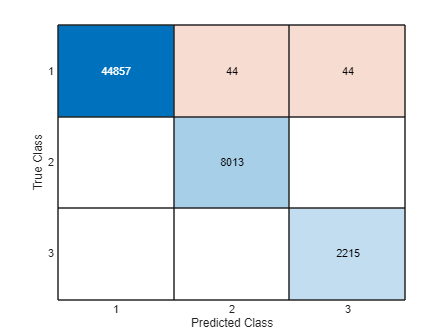

AUC = 0.0013

AUC = 0.9516

AUC = 0.9996

       11073



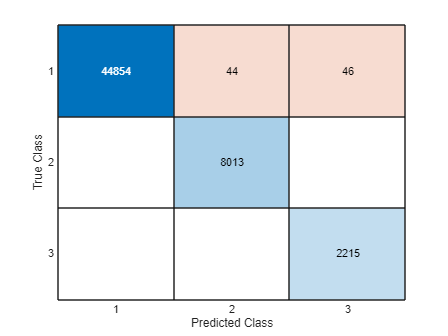

AUC = 0.0013

AUC = 0.9516

AUC = 0.9996

       11006



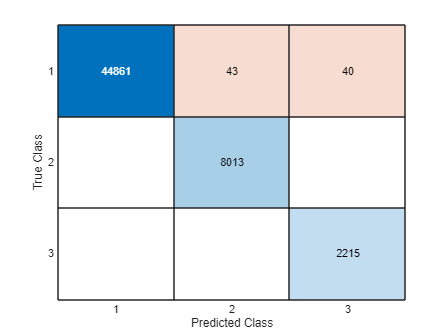

AUC = 0.0012

AUC = 0.9517

AUC = 0.9996

       11032



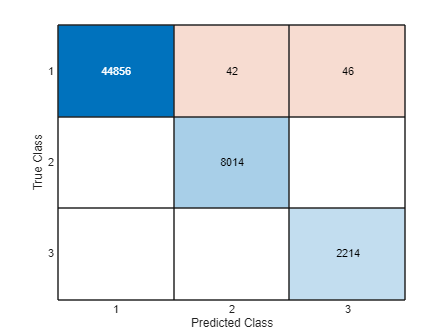

AUC = 0.0013

AUC = 0.9516

AUC = 0.9996

       11015



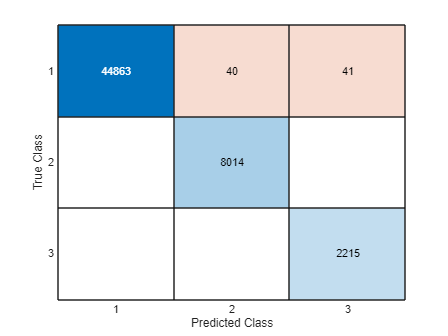

AUC = 0.0012

AUC = 0.9517

AUC = 0.9996

       10986



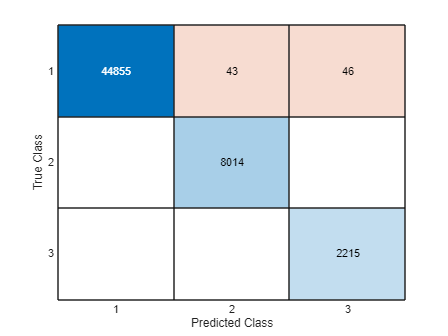

AUC = 0.0013

AUC = 0.9516

AUC = 0.9996

       11046



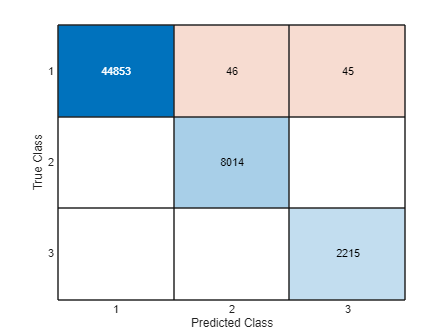

AUC = 0.0013

AUC = 0.9516

AUC = 0.9996

       11066



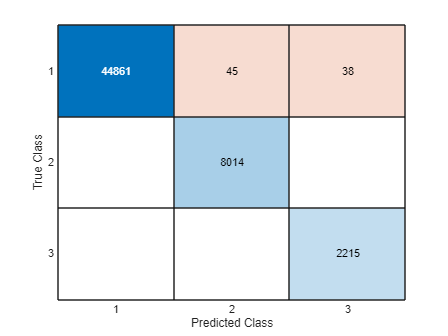

AUC = 0.0011

AUC = 0.9517

AUC = 0.9996

       11024



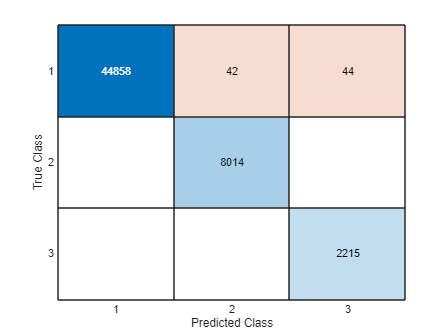

AUC = 0.0012

AUC = 0.9517

AUC = 0.9996

       11050



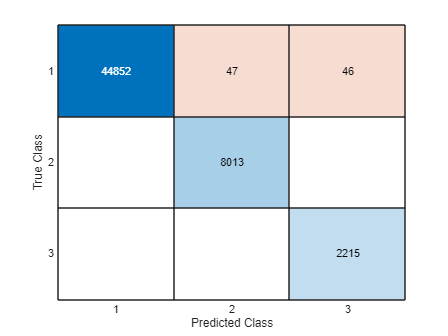

AUC = 0.0013

AUC = 0.9516

AUC = 0.9996


sesID1 = cell2mat(sesID');

% Sort SesID1 by File then Time
[sesIDsort,sortidx]=sortrows(sesID1,[1,2]);


% extract the features (each group is an element of the cell array)
ops.nGroup  = length(dat);

x = cell2mat(dat');
xsort=x(sortidx,:);

%define the groups (1:length(dat))
labels = cell2mat(cellfun(@(a,b) b*ones(size(a,1),1),dat,num2cell(1:length(dat)),'uni',0)');

labels_sort=actual(sortidx);

% randomly sort for cross validation
%ops.rix  = (mod(sesID1(:,1),2)==1);
%ops.rix = true(size(group,1),1);
%ops.rix = sesID1(:,1)~=1;
aucs=[];
for fold = 1:10
    
    c = cvpartition(group,KFold=10);
    
    if fold>1
        disp(sum(training(c,fold)~=ops.rix))
    end
    ops.rix = training(c,fold);

    if load_model==false

        %set up classifer
    
        
        ops.N = sum(ops.rix);         % Number of observations in the training sample
        ops.t = templateTree('MaxNumSplits',ops.N/4);
        ops.NumLearningCycles = 115;
        ops.Learners = ops.t;
        ops.LearnRate = 0.1;
        ops.Method = 'RUSBoost';
        
        %train model
    
        rusTree = fitcensemble(x(ops.rix ,:),group(ops.rix ,:),'Method',ops.Method, ...
            'NumLearningCycles',ops.NumLearningCycles,'Learners',ops.Learners,'LearnRate',ops.LearnRate);
    end

    figure
    [label,conf] = predict(rusTree,x(ops.rix ,:));
    actual = group(ops.rix ,:);
    C = confusionmat(actual,label);
    C1 = C./nansum(C,2);
    C2 = C./nansum(C,1);
    
    confusionchart(C);
    
    for i = 1:3
        [X,Y,~,AUC] = perfcurve(actual,label,i);
        aucs(i,fold)=AUC;
        display(AUC);
    end
end


disp(['Interictal AUC (k=10): ', num2str(1-mean(aucs(1,:))), ' ± ', num2str(std(aucs(1,:)))])

Interictal AUC (k=10): 0.99875 ± 6.3759e-05


disp(['Seizure AUC (k=10): ', num2str(mean(aucs(2,:))), ' ± ', num2str(std(aucs(2,:)))])

Seizure AUC (k=10): 0.95165 ± 6.842e-05


disp(['Noise AUC (k=10): ', num2str(mean(aucs(3,:))), ' ± ', num2str(std(aucs(3,:)))])

Noise AUC (k=10): 0.99959 ± 2.7508e-05


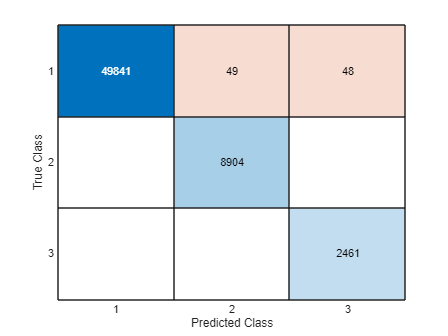


%set up classifer
ops.rix = true(size(group,1),1);

sesID1 = cell2mat(sesID');
% extract the features (each group is an element of the cell array)
ops.nGroup  = length(dat);

x = cell2mat(dat');


% ops.N = sum(ops.rix);         % Number of observations in the training sample
% ops.t = templateTree('MaxNumSplits',ops.N/4);
% ops.NumLearningCycles = 115;
% ops.Learners = ops.t;
% ops.LearnRate = 0.1;
% ops.Method = 'RUSBoost';

%train model
% rusTree = fitcensemble(x(ops.rix ,:),group(ops.rix ,:),'Method',ops.Method, ...
%     'NumLearningCycles',ops.NumLearningCycles,'Learners',ops.Learners,'LearnRate',ops.LearnRate);

figure
[label,conf] = predict(rusTree,x(ops.rix ,:));
actual = group(ops.rix ,:);
C = confusionmat(actual,label);
C1 = C./nansum(C,2);
C2 = C./nansum(C,1);

confusionchart(C);


for i = 1:3
    [X,Y,~,AUC] = perfcurve(actual,label,i);
    display(AUC);
end

AUC = 0.0012

AUC = 0.9516

AUC = 0.9996

training=x;
%save (does not resave features, does save filename)
save(ops.ClassifierFileOutput,'ops','rusTree','group','sessions','-v7.3')
% rusTree.ScoreTransform = @mysoftmax;


## 2.c. Evaluate Model

all_class_files=[]


all_class_files =

     []




sesID1 = cell2mat(sesID');

% Sort SesID1 by File then Time
[sesIDsort,sortidx]=sortrows(sesID1,[1,2]);


% extract the features (each group is an element of the cell array)
ops.nGroup  = length(dat);

x = cell2mat(dat');
x_sort=x(sortidx,:);

%define the groups (1:length(dat))
labels = cell2mat(cellfun(@(a,b) b*ones(size(a,1),1),dat,num2cell(1:length(dat)),'uni',0)');

labels_sort=actual(sortidx);

all_class_files = 3

Error using bootci>bootbca (line 265)
With 'type' equal to 'bca' (the default), BOOTCI uses JACKKNIFE internally. The call to JACKKNIFE failed with function '@(idx)oneBootXYT(idx,scores(sorted),W>0,xValsFixed,tValsFixed,processNaN,afx,afy)'. Try using a confidence interval type other than 'bca'.

Error in bootci (line 171)
        [ci,bootstat] = bootbca(obsstat,nboot,fun,alpha,weights,bootstrpOptions,data{:});

Error in <a href="ma


labels_sort
[predictions,conf]=rusTree.predict(x_sort);

binary_conf = [conf(:,1)+conf(:,3), conf(:,2)];
binary_label = labels_sort==2;
binary_predictions = predictions==2;


class_names=[{'Interictal'},{'Seizure'},{'Noise'}]

rocObj=rocmetrics(binary_label,binary_conf,unique(binary_label))
plot(rocObj,AverageROCType="micro")




text_label = strings(size(binary_predictions));        % create string array
text_label(binary_predictions == 0) = "Non-Seizure";
text_label(binary_predictions == 1) = "Seizure";

text_actual = strings(size(binary_label));        % create string array
text_actual(binary_label == 0) = "Non-Seizure";
text_actual(binary_label == 1) = "Seizure";


confusionchart(text_actual,text_label);
title(sprintf(["Binary Ground Truth ~= Binary Label \n By Epoch"]));

sens=C(1,1)/(C(1,1)+C(1,2))
spec=C(2,2)/(C(2,2)+C(2,1))

allLabels=unique(labels_sort)

currentLabel=allLabels(i);
display(currentLabel);
scores = conf(:,currentLabel); 
[X, Y, T, AUC] = perfcurve(actual, scores, currentLabel,'NBoot',1000);

bouts=getBouts(binary_label);

errors=binary_label~=binary_predictions
bouts=getBouts(errors);

plot(binary_label~=binary_predictions)
title(sprintf("Binary Ground Truth Label ~= Binary Predictions \n By Epoch"))

%%

% 
% 

%%


for i = 1:length(allLabels) % For all unique labels in ground truth
    currentLabel=allLabels(i);
    display(currentLabel);
    scores = conf(:,currentLabel); 
    [X, Y, T, AUC] = perfcurve(actual, scores, currentLabel,'NBoot',1000);
    
    % Plot ROC
    figure;
    hold on
    plot(X, Y, 'LineWidth', 2);
    plot([0 1], [0 1], 'k--');   % chance line    
    xlabel('False Positive Rate');
    ylabel('True Positive Rate');
    title([sprintf('ROC Curve, Class %1i ',i), sprintf('AUC = %.3f', AUC)]);
    grid on;
    hold off
end

% figure
% grid off
% plot(conf(:,1))
% hold on
% plot(conf(:,2))
% plot(conf(:,3))
% plot(actual)
% for i=0:20
%     figure
%     hold on
%     display([1+(i*1000),(i+1)*1000])
%     plot(conf(1+(i*1000):((i+1)*1000),1),legend('Probability Interictal'))
%     plot(conf(1+(i*1000):((i+1)*1000),2),legend('Probability Seizure'))
%     plot(conf(1+(i*1000):((i+1)*1000),3),legend('Probability Noise'))
%     plot(actual(1+(i*1000):((i+1)*1000)),legend('Label'))
% end


rocObj=rocmetrics(actual,conf,unique(actual))
plot(rocObj,AverageROCType="micro")

%%
sesID1 = cell2mat(sesID');

% Sort SesID1 by File then Time
[sesIDsort,sortidx]=sortrows(sesID1,[1,2]);

x = cell2mat(dat');
x_sort=x(sortidx,:);

%define the groups (1:length(dat))
labels = cell2mat(cellfun(@(a,b) b*ones(size(a,1),1),dat,num2cell(1:length(dat)),'uni',0)');
labels_sort=actual(sortidx);

eph=[]


eph =

     []




for fold = 1:10
    
    c = cvpartition(labels_sort,KFold=10);
    
    if fold>1
        disp(sum(training(c,fold)~=ops.rix))
    end
    cv_keep = training(c,fold);


    
    cv_labels=labels_sort(cv_keep);
    % extract the features (each group is an element of the cell array)
    ops.nGroup  = length(dat);
    
    [predictions,conf]=rusTree.predict(x_sort(cv_keep,:));
    
    binary_conf = [conf(:,1)+conf(:,3), conf(:,2)];
    binary_label = cv_labels==2;
    binary_predictions = predictions==2;


    text_pred = strings(size(binary_predictions));        % create string array
    text_pred(binary_predictions == 0) = "Non-Seizure";
    text_pred(binary_predictions == 1) = "Seizure";
    
    text_label = strings(size(binary_label));        % create string array
    text_label(binary_label == 0) = "Non-Seizure";
    text_label(binary_label == 1) = "Seizure";

    errors=binary_predictions~=binary_label;
    bouts=getBouts(errors);

    predictions_hours=length(predictions)*(4/3600);
    errors_per_hour=sum(errors)/predictions_hours;

    eph=[eph,errors_per_hour];
end

        6131

        6131

        6131

        6130

        6130

        6130

        6130

        6130

        6130




eph

eph =    0.782991680713392   0.734068005510041   0.783005872544044   0.701442760820706   0.685117720624218   0.652493067261160   0.750367027350334   0.782991680713392   0.734054700668805   0.750367027350334


mean(eph)

ans =    0.735689954355643


std(eph)

ans =    0.044474691398263


datafile = 'R:\ASommer\PilocarpineRecordings\Tests\UnpluggedTest\2-17-2026(14.45)\RHS_260217_145001\amplifier.dat'
xmlfile = strrep(datafile,'.dat','.xml')

xml = LoadXml(xmlfile)
data = LoadBinary(datafile,'nchannels',xml.nChannels,'frequency',xml.SampleRate,'channels',[1,5],'duration', 20,'start',0);
s
outname="H:\audio\noise.wav"
audiowrite(outname,data,20000);


datafile='R:\ASommer\PilocarpineRecordings\PTP_5.1\2-11-2026(9.8)\RHS_260211_091012\amplifier.dat'
xmlfile = strrep(datafile,'.dat','.xml')

xml = LoadXml(xmlfile)
data = LoadBinary(datafile,'nchannels',xml.nChannels,'frequency',xml.SampleRate,'channels',[1,5],'duration', 60,'start',3788);

outname="H:\audio\seizure-nPTP5.1-d0211-t091012-ts3788.wav"
audiowrite(outname,data,20000);